clear
clc
close all

%% Load Dataset

T = readtable("data/master_dataset.csv");

%% Filter to Driver and Team

T = T(strcmp(T.Driver, "PIA") & strcmp(T.Team, "McLaren"), :);

fprintf("Rows remaining after driver/team filter: %d\n", height(T))

Rows remaining after driver/team filter: 1870


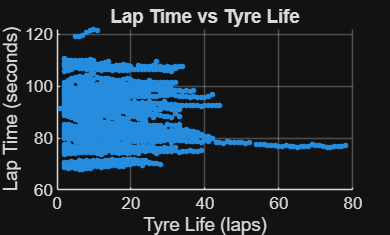


figure

scatter(T.TyreLife, T.LapTime, 8, 'filled')

xlabel('Tyre Life (laps)')
ylabel('Lap Time (seconds)')
title('Lap Time vs Tyre Life')

grid on


%% Keep Dry Tyres Only

dryTyres = ["SOFT","MEDIUM","HARD"];

T = T(ismember(string(T.Compound), dryTyres), :);

unique(T.Compound)

ans = 3×1 cell array
    {'HARD'  }
    {'MEDIUM'}
    {'SOFT'  }



T = sortrows(T);

T.RowID = (1:height(T))';

summary(T)


T: 1716×14 table

Variables:

    Year: double
    Event: cell array of character vectors
    Driver: cell array of character vectors
    Team: cell array of character vectors
    LapNumber: double
    Stint: double
    TyreLife: double
    Compound: cell array of character vectors
    LapTime: double
    Position: double
    TrackTemp: double
    AirTemp: double
    FuelEstimate: double
    RowID: double

Statistics for applicable variables:

                    NumMissing        Min           Median           Max              Mean             Std     

    Year                0              2024            2024     


size(T)

ans =         1716          14


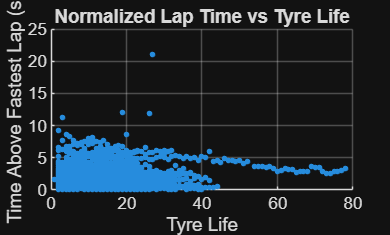


%% Normalize Lap Time by Event

groups = findgroups(T.Event);

fastestLap = splitapply(@min, T.LapTime, groups);

T.NormalizedLap = T.LapTime - fastestLap(groups);

figure

scatter(T.TyreLife,T.NormalizedLap,8,'filled')

xlabel("Tyre Life")
ylabel("Time Above Fastest Lap (s)")
title("Normalized Lap Time vs Tyre Life")

grid on


%% Remove Pit In and Out Laps

keep = true(height(T),1);

for i = 1:height(T)-1

if strcmp(T.Driver{i}, T.Driver{i+1}) && ...
 strcmp(T.Event{i}, T.Event{i+1}) && ...
 T.Stint(i) ~= T.Stint(i+1)

 keep(i) = false;
 keep(i+1) = false;
end

end

T = T(keep,:);

%% Remove Short Stints

groups = findgroups(T.Event,T.Driver,T.Stint);

lapsPerStint = splitapply(@numel,T.LapTime,groups);

T = T(lapsPerStint(groups) >= 5,:);

T.RowID = (1:height(T))';
writetable(T,"data/clean_dataset.csv")

fprintf("clean_dataset.csv written: %d rows\n", height(T))

clean_dataset.csv written: 1616 rows
